MPZ_st.name='MPZ'; 
MPZ_st.lat=51.5303;
MPZ_st.lon=12.9339;
MPZ_st.alt=86;
MPZ_st.env='con';
MPZ_st.footp='U';


MPZ_rd=read_betsy('MPZ_2007_2017',MPZ_st.name);

datevec(MPZ_rd.Time(1))

ans =         2007           1           2           0           0           0

datevec(MPZ_rd.Time(end))

ans =         2018           1           1           0           0           0

prctile(MPZ_rd.U_S,[5 50 95])

ans =     6.8600   20.0500   34.3300

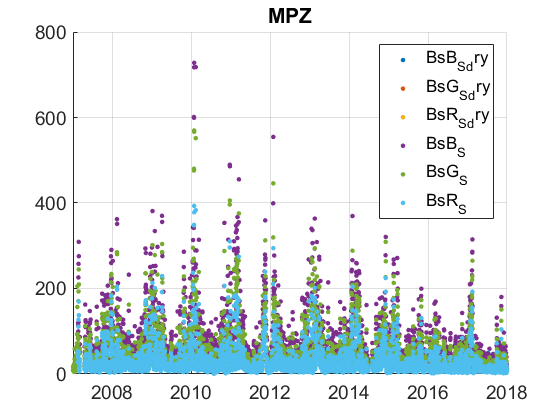

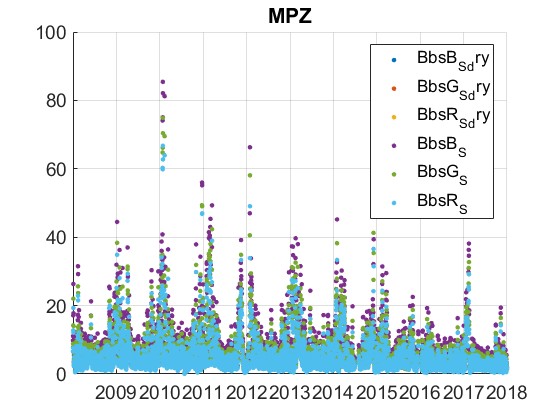

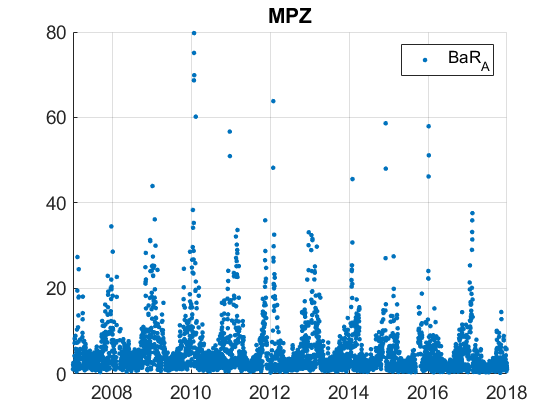

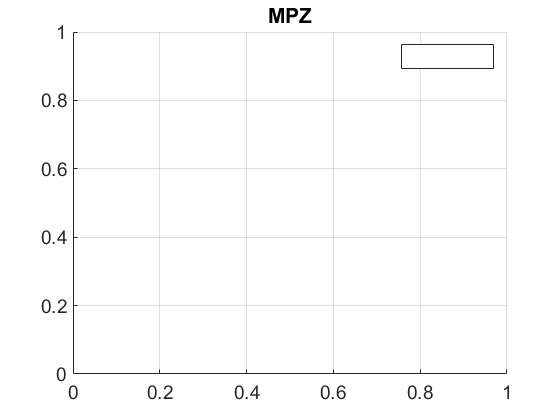

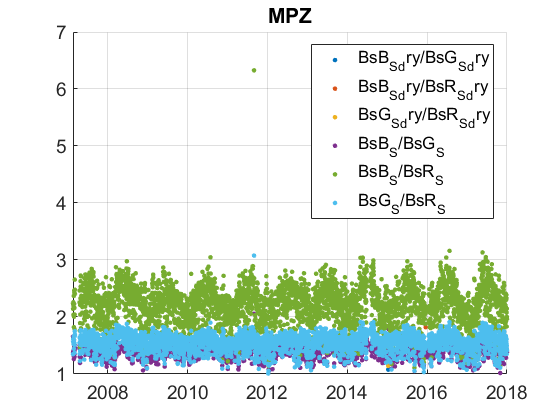

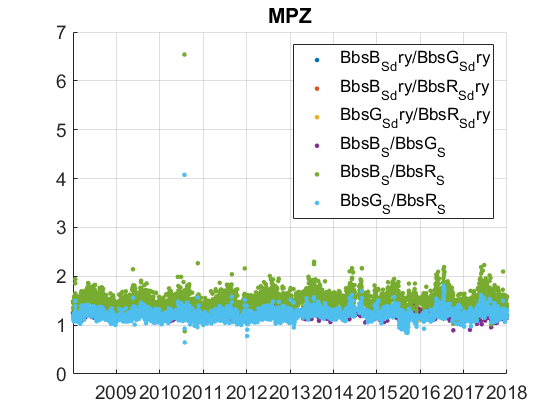

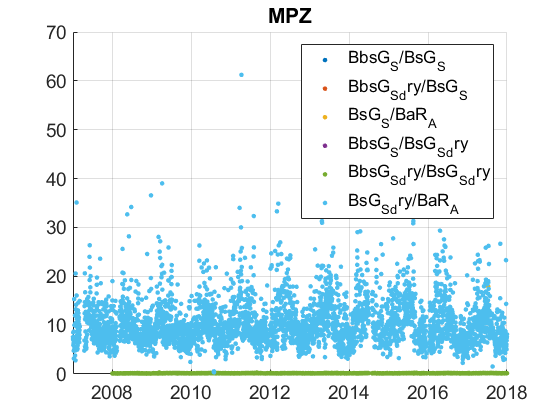

plotFigControl(MPZ_rd,MPZ_st.name);

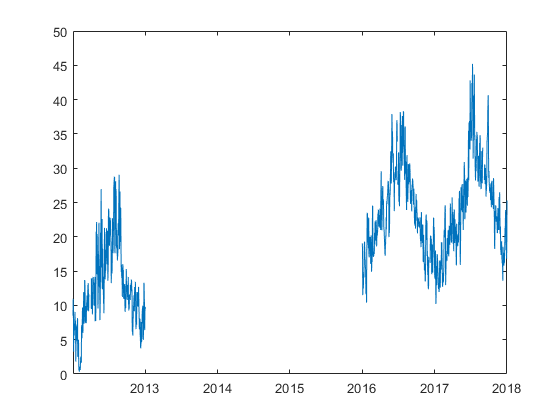


figure;
plot(MPZ_rd.Time,MPZ_rd.U_S);

% 1 size cut, ok
% sc: ok, max in winter, no negatives
% abs: 2 size cut, max in winter, no negatives


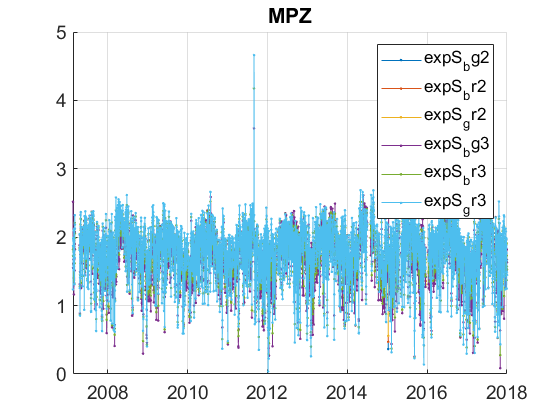

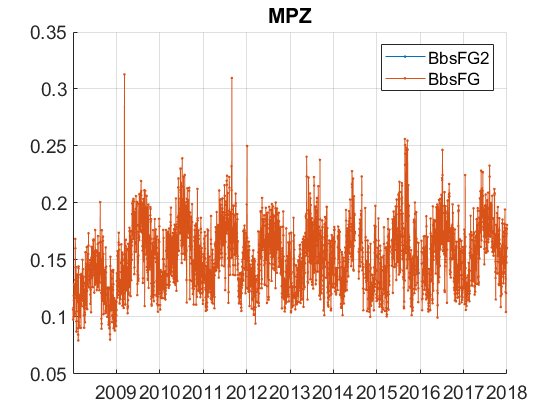

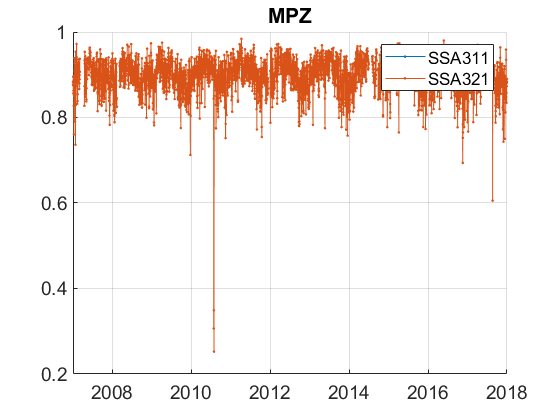

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
MPZ_cal=compute_exp_SSA(MPZ_rd,lambdaSC, lambdaAE);
plotFigControl_cal(MPZ_cal, MPZ_st.name);

%Questions:
%problems:
%SCA: When was the nephelometer change from 3561 to 3563 ?
% sca+ abs: are the higher values at the end of January 2017- begin of February 2017 real ? they have to be invalidated ?
%sca: the ratio BsG/BsR and BsB/BsR made a jump in March 2008. Is there any changes ?
%sca: the BbsF fraction is much lower in 2008. Do you know why ?
%backsca: the BbsB/BbsG ratio is strange in November 2015: is it real ?

%abs: are the low values of December 2011-January 2012 real ?

period1=timerange('2008-01-01','2008-12-31');
period2=timerange('2009-01-01','2009-12-31');
TT1=MPZ_cal(period1,:);
TT2=MPZ_cal(period2,:);
nanmean(TT1.BbsFG)

ans = 0.1268

nanmean(TT2.BbsFG)

ans = 0.1555


MPZ_tr=MPZ_rd;
%MPZ_tr=outerjoin(MPZ_rd, MPZ_cal);
MPZ_tr.y=year(MPZ_tr.Time);
% begin at the beginning of a year: 2007
% end 2017

%not necessary to analysee dry
MPZ_tr.U_S=[];
names=fieldnames(MPZ_tr);
c=endsWith(names,["dry";"3"]) | startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]);
N=names(c);
for i=1:length(N)
    MPZ_tr.(N{i})=[];
end
%scatG: 2007-2017
%MPZ_tr.BsB_S=[];
MPZ_tr.BsR_S=[];
%Bsc: 2008-2017
MPZ_tr.BbsB_S=[];
MPZ_tr.BbsR_S=[];
%abs: 12.12.2011-5.1.2012 zu invalidieren
P=timerange('2011-12-12','2013-01-05');
MPZ_tr.BaR_A(P)=NaN;
%sonst 2007-2017 zu brauchen

%corrected abs to green for SSA trend
MPZ_tr.BaR_A=MPZ_tr.BaR_A.*(637/550);
%recalculate values
MPZ_cal2=compute_exp_SSA(MPZ_tr,lambdaSC, lambdaAE);
%BbsFG 2008 zu invalidieren: zu klein, weisst man nicht warum
P=timerange('2008-01-01','2008-12-31');
MPZ_cal2.BbsFG(P)=NaN;
MPZ_tr=outerjoin(MPZ_tr, MPZ_cal2);
 
%SSA: 2007-2017

Iterating trend, loop:2, trend: -0.0064937/day = -2.3718/year
Iterating trend, loop:3, trend: -0.0066737/day = -2.4376/year
Iteration stopped, trend: -0.0066736/day = -2.4375/year
Final estimate on noise autocorrelation=-0.0033208, Noise standard deviation:27.8649
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0019932+9.8846e-07i    -0.011612-2.9075e-06i]/day = [-0.72802+0.00036104i        -4.2412-0.001062i]/yr
Round:200/500, Trend BCI: [-0.0021567-5.5325e-07i    -0.011456+1.0462e-06i]/day = [-0.78774-0.00020208i      -4.1845+0.00038211i]/yr
Round:300/500, Trend BCI: [-0.0023195+3.7851e-06i    -0.011456+1.0462e-06i]/day = [-0.8472+0.0013825i      -4.1845+0.00038211i]/yr
Round:400/500, Trend BCI: [-0.00225+4.9054e-07i    -0.011415+1.0552e-06i]/day = [-0.82182+0.00017917i      -4.1695+0.00038543i]/yr
Round:500/500, Trend BCI: [-0.002342+6.3306e-07i    -0.011231+1.4361e-06i]/day = [-0.85542+0.00023123i       -4.102+0.00052452i]/yr
Trend BCI: [-0.002342+6.3306e-07i    -0.011231+1.4

Iterating trend, loop:2, trend: -0.011224/day = -4.0996/year
Iterating trend, loop:3, trend: -0.010303/day = -3.7632/year
Iteration stopped, trend: -0.010298/day = -3.7613/year
Final estimate on noise autocorrelation=-0.080284, Noise standard deviation:27.7086
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0053269+6.6184e-06i    -0.014784+1.6858e-05i]/day = [-1.9457+0.0024174i       -5.3997+0.0061575i]/yr
Round:200/500, Trend BCI: [-0.0059064+4.359e-05i     -0.01406+6.6429e-06i]/day = [-2.1573+0.015921i       -5.1355+0.0024263i]/yr
Round:300/500, Trend BCI: [-0.0059521+3.2796e-05i     -0.01406+6.6429e-06i]/day = [-2.174+0.011979i       -5.1355+0.0024263i]/yr
Round:400/500, Trend BCI: [-0.0059064+4.359e-05i    -0.014312-3.6707e-07i]/day = [-2.1573+0.015921i      -5.2275-0.00013407i]/yr
Round:500/500, Trend BCI: [-0.0059064+4.359e-05i    -0.014134-2.7722e-06i]/day = [-2.1573+0.015921i       -5.1626-0.0010126i]/yr
Trend BCI: [-0.0059064+4.359e-05i    -0.014134-2.7722e-06i]/day = [

Iterating trend, loop:2, trend: -0.0022605/day = -0.82566/year
Iterating trend, loop:3, trend: -0.0018976/day = -0.69311/year
Iteration stopped, trend: -0.0018972/day = -0.69296/year
Final estimate on noise autocorrelation=-0.069911, Noise standard deviation:28.1027
Starting MC. rounds: 500
Round:100/500, Trend BCI: [1.0986e-06-3.2285e-07i   -0.0067979+8.8382e-06i]/day = [0.00040128-0.00011792i       -2.4829+0.0032281i]/yr
Round:200/500, Trend BCI: [1.0986e-06-3.2285e-07i    -0.0068144+1.047e-05i]/day = [0.00040128-0.00011792i        -2.489+0.0038243i]/yr
Round:300/500, Trend BCI: [-0.00017141-4.3184e-06i   -0.0066528+1.4098e-05i]/day = [-0.062606-0.0015773i       -2.4299+0.0051492i]/yr
Round:400/500, Trend BCI: [-0.00017141-4.3184e-06i   -0.0065826+1.9859e-05i]/day = [-0.062606-0.0015773i       -2.4043+0.0072533i]/yr
Round:500/500, Trend BCI: [-0.00015279+2.5748e-05i   -0.0065484+1.7145e-05i]/day = [-0.055808+0.0094044i       -2.3918+0.0062623i]/yr
Trend BCI: [-0.00015279+2.5748e-05i 

Iterating trend, loop:2, trend: -0.004616/day = -1.686/year
Iterating trend, loop:3, trend: -0.0047443/day = -1.7328/year
Iteration stopped, trend: -0.0047443/day = -1.7329/year
Final estimate on noise autocorrelation=-0.0079873, Noise standard deviation:20.8456
Starting MC. rounds: 500
Round:100/500, Trend BCI: [3.7895e-05+8.6901e-07i    -0.0080619-4.433e-07i]/day = [0.013841+0.0003174i      -2.9446-0.00016192i]/yr
Round:200/500, Trend BCI: [-0.0010954-1.314e-06i   -0.0080471+4.7166e-06i]/day = [-0.40009-0.00047993i       -2.9392+0.0017227i]/yr
Round:300/500, Trend BCI: [-0.0012095-1.9006e-06i   -0.0079063+1.2589e-06i]/day = [-0.44177-0.00069421i      -2.8878+0.00045982i]/yr
Round:400/500, Trend BCI: [-0.001296+1.2533e-06i   -0.0079664-2.2575e-06i]/day = [-0.47336+0.00045778i      -2.9097-0.00082455i]/yr
Round:500/500, Trend BCI: [-0.0014003-3.1142e-06i   -0.0080785-1.7252e-06i]/day = [-0.51145-0.0011375i      -2.9507-0.00063013i]/yr
Trend BCI: [-0.0014003-3.1142e-06i   -0.0080785-1.7

Iterating trend, loop:2, trend: -0.0080099/day = -2.9256/year
Iterating trend, loop:3, trend: -0.0072978/day = -2.6655/year
Iteration stopped, trend: -0.0072936/day = -2.664/year
Final estimate on noise autocorrelation=-0.093241, Noise standard deviation:20.7929
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0034638+2.6481e-05i   -0.0099664+4.9307e-07i]/day = [-1.2652+0.0096722i      -3.6402+0.00018009i]/yr
Round:200/500, Trend BCI: [-0.0040585-1.6727e-07i    -0.010009+5.8358e-06i]/day = [-1.4824-6.1094e-05i       -3.6556+0.0021315i]/yr
Round:300/500, Trend BCI: [-0.0040301-1.7307e-05i    -0.010158+1.0518e-05i]/day = [-1.472-0.0063213i       -3.7104+0.0038418i]/yr
Round:400/500, Trend BCI: [-0.0038507+1.2526e-05i    -0.010208+1.4659e-05i]/day = [-1.4065+0.0045753i       -3.7283+0.0053542i]/yr
Round:500/500, Trend BCI: [-0.0039569-1.2305e-05i    -0.010195+2.4512e-05i]/day = [-1.4453-0.0044946i        -3.7239+0.008953i]/yr
Trend BCI: [-0.0039569-1.2305e-05i    -0.010195+2.4512e-0

Iterating trend, loop:2, trend: 3.1194e-05/day = 0.011394/year
Iterating trend, loop:3, trend: -9.0333e-05/day = -0.032994/year
Iteration stopped, trend: -9.0626e-05/day = -0.033101/year
Final estimate on noise autocorrelation=-0.048908, Noise standard deviation:21.3402
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.00016465-8.7424e-06i   5.9238e-05-1.9592e-05i]/day = [-0.060137-0.0031932i      0.021637-0.0071561i]/yr
Round:200/500, Trend BCI: [-0.00016465-8.7424e-06i   5.2993e-05+3.7699e-06i]/day = [-0.060137-0.0031932i      0.019356+0.0013769i]/yr
Round:300/500, Trend BCI: [-0.00015636-5.838e-06i   5.2993e-05+3.7699e-06i]/day = [-0.057112-0.0021323i      0.019356+0.0013769i]/yr
Round:400/500, Trend BCI: [-7.1875e-06-5.4852e-06i    0.0039347+1.0802e-05i]/day = [-0.0026252-0.0020035i        1.4371+0.0039455i]/yr
Round:500/500, Trend BCI: [0.00015116-4.1379e-06i    -0.004032-5.5248e-06i]/day = [0.055211-0.0015114i       -1.4727-0.0020179i]/yr
Trend BCI: [0.00015116-4.1379e-06i  

Iterating trend, loop:2, trend: -0.00055767/day = -0.20369/year
Iterating trend, loop:3, trend: -0.0005714/day = -0.2087/year
Iteration stopped, trend: -0.00057141/day = -0.20871/year
Final estimate on noise autocorrelation=0.023539, Noise standard deviation:2.6199
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0011094 -0.00017031]/day = [-0.4052   -0.062205]/yr
Round:200/500, Trend BCI: [-0.001079 -0.00010367]/day = [-0.39411   -0.037867]/yr
Round:300/500, Trend BCI: [-0.0010196 -5.7548e-05]/day = [-0.37241   -0.021019]/yr
Round:400/500, Trend BCI: [-0.0010092 -6.3125e-05]/day = [-0.36861   -0.023057]/yr
Round:500/500, Trend BCI: [-0.0009964 -5.8744e-05]/day = [-0.36394   -0.021456]/yr
Trend BCI: [-0.0009964 -5.8744e-05]/day = [-0.36394   -0.021456]/yr


Iterating trend, loop:2, trend: -0.0010958/day = -0.40023/year
Iterating trend, loop:3, trend: -0.0010278/day = -0.37541/year
Iteration stopped, trend: -0.0010275/day = -0.37529/year
Final estimate on noise autocorrelation=-0.077134, Noise standard deviation:2.5739
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.00066233+2.3488e-06i   -0.0014761-6.5089e-07i]/day = [-0.24191+0.0008579i     -0.53916-0.00023774i]/yr
Round:200/500, Trend BCI: [-0.00067337+1.979e-06i    -0.001425+1.0593e-06i]/day = [-0.24595+0.00072284i      -0.52047+0.0003869i]/yr
Round:300/500, Trend BCI: [-0.00063829-2.1509e-06i   -0.0013917-1.2776e-06i]/day = [-0.23314-0.0007856i     -0.50831-0.00046665i]/yr
Round:400/500, Trend BCI: [-0.00064928+2.2725e-06i     -0.0014349-1.86e-06i]/day = [-0.23715+0.00083002i     -0.52411-0.00067937i]/yr
Round:500/500, Trend BCI: [-0.00064744+3.3081e-06i    -0.0014252-2.848e-06i]/day = [-0.23648+0.0012083i      -0.52056-0.0010402i]/yr
Trend BCI: [-0.00064744+3.3081e-06i    -0.0

Iterating trend, loop:2, trend: -0.00066695/day = -0.2436/year
Iterating trend, loop:3, trend: -0.00068188/day = -0.24906/year
Iteration stopped, trend: -0.0006819/day = -0.24906/year
Final estimate on noise autocorrelation=-0.073703, Noise standard deviation:2.2694
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.00024776+1.0412e-06i    -0.001059-8.6829e-07i]/day = [-0.090493+0.00038031i      -0.3868-0.00031714i]/yr
Round:200/500, Trend BCI: [-0.00027701-1.1471e-06i   -0.0010431-1.5056e-06i]/day = [-0.10118-0.00041897i     -0.38098-0.00054994i]/yr
Round:300/500, Trend BCI: [-0.00027701-1.1471e-06i   -0.0010362-2.2722e-06i]/day = [-0.10118-0.00041897i     -0.37846-0.00082993i]/yr
Round:400/500, Trend BCI: [-0.00029087-1.2213e-06i   -0.0010362-2.2722e-06i]/day = [-0.10624-0.00044609i     -0.37846-0.00082993i]/yr
Round:500/500, Trend BCI: [-0.0002989-1.7321e-06i   -0.0010314+1.6835e-06i]/day = [-0.10917-0.00063264i     -0.37673+0.00061489i]/yr
Trend BCI: [-0.0002989-1.7321e-06i   -

Iterating trend, loop:2, trend: -0.00093422/day = -0.34122/year
Iterating trend, loop:3, trend: -0.0008407/day = -0.30707/year
Iteration stopped, trend: -0.00083988/day = -0.30677/year
Final estimate on noise autocorrelation=-0.1467, Noise standard deviation:2.3635
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.00054613+2.1656e-06i   -0.0011562+1.0149e-07i]/day = [-0.19947+0.000791i     -0.42232+3.7069e-05i]/yr
Round:200/500, Trend BCI: [-0.00055841+2.5334e-06i    -0.0011443-1.624e-06i]/day = [-0.20396+0.00092534i     -0.41797-0.00059317i]/yr
Round:300/500, Trend BCI: [-0.00055106+1.8305e-06i    -0.0011443-1.624e-06i]/day = [-0.20128+0.00066858i     -0.41797-0.00059317i]/yr
Round:400/500, Trend BCI: [-0.00054038-1.9977e-06i   -0.0011463+3.1938e-06i]/day = [-0.19737-0.00072965i       -0.4187+0.0011665i]/yr
Round:500/500, Trend BCI: [-0.00053527+9.6651e-07i   -0.0011481-2.1293e-06i]/day = [-0.19551+0.00035302i     -0.41935-0.00077772i]/yr
Trend BCI: [-0.00053527+9.6651e-07i   -0.

Iterating trend, loop:2, trend: -0.00025397/day = -0.092762/year
Iterating trend, loop:3, trend: -0.00026597/day = -0.097144/year
Iteration stopped, trend: -0.00026602/day = -0.097162/year
Final estimate on noise autocorrelation=-0.079135, Noise standard deviation:2.3388
Starting MC. rounds: 500
Round:100/500, Trend BCI: [8.3959e-07-2.8595e-06i  -0.00061893+1.1476e-06i]/day = [0.00030666-0.0010444i     -0.22606+0.00041915i]/yr
Round:200/500, Trend BCI: [2.001e-05-1.469e-06i   -0.0005949+8.0621e-07i]/day = [0.0073087-0.00053654i     -0.21729+0.00029447i]/yr
Round:300/500, Trend BCI: [2.001e-05-1.469e-06i  -0.00058741-6.6322e-07i]/day = [0.0073087-0.00053654i     -0.21455-0.00024224i]/yr
Round:400/500, Trend BCI: [-2.1022e-05-4.0879e-06i  -0.00058389-1.2543e-06i]/day = [-0.0076781-0.0014931i     -0.21326-0.00045815i]/yr
Round:500/500, Trend BCI: [2.4805e-05+2.5479e-06i   -0.0005854-1.8261e-06i]/day = [0.0090601+0.00093064i       -0.21382-0.000667i]/yr
Trend BCI: [2.4805e-05+2.5479e-06i  

Iterating trend, loop:2, trend: 3.3171e-06/day = 0.0012116/year
Iterating trend, loop:3, trend: 3.6472e-06/day = 0.0013322/year
Iteration stopped, trend: 3.6484e-06/day = 0.0013326/year
Final estimate on noise autocorrelation=0.23356, Noise standard deviation:0.012723
Starting MC. rounds: 500
Round:100/500, Trend BCI: [1.1203e-06  6.4553e-06]/day = [0.00040919   0.0023578]/yr
Round:200/500, Trend BCI: [1.4026e-06  6.5022e-06]/day = [0.00051231   0.0023749]/yr
Round:300/500, Trend BCI: [1.1624e-06  6.3665e-06]/day = [0.00042457   0.0023254]/yr
Round:400/500, Trend BCI: [1.0778e-06  6.3551e-06]/day = [0.00039366   0.0023212]/yr
Round:500/500, Trend BCI: [1.1064e-06  6.2797e-06]/day = [0.00040411   0.0022937]/yr
Trend BCI: [1.1064e-06  6.2797e-06]/day = [0.00040411   0.0022937]/yr


Iterating trend, loop:2, trend: 8.5684e-07/day = 0.00031296/year
Iterating trend, loop:3, trend: 1.156e-06/day = 0.00042222/year
Iteration stopped, trend: 1.1566e-06/day = 0.00042245/year
Final estimate on noise autocorrelation=0.26433, Noise standard deviation:0.012431
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-1.3144e-06  4.0668e-06]/day = [-0.00048008   0.0014854]/yr
Round:200/500, Trend BCI: [-1.5811e-06  4.1502e-06]/day = [-0.00057751   0.0015159]/yr
Round:300/500, Trend BCI: [-1.6369e-06  4.1072e-06]/day = [-0.00059789   0.0015002]/yr
Round:400/500, Trend BCI: [-1.6369e-06   3.971e-06]/day = [-0.00059789   0.0014504]/yr
Round:500/500, Trend BCI: [-1.6185e-06  3.9449e-06]/day = [-0.00059114   0.0014409]/yr
Trend BCI: [-1.6185e-06  3.9449e-06]/day = [-0.00059114   0.0014409]/yr


Iterating trend, loop:2, trend: 4.8059e-06/day = 0.0017554/year
Iterating trend, loop:3, trend: 4.9736e-06/day = 0.0018166/year
Iteration stopped, trend: 4.9739e-06/day = 0.0018167/year
Final estimate on noise autocorrelation=0.10699, Noise standard deviation:0.011933
Starting MC. rounds: 500
Round:100/500, Trend BCI: [2.3016e-06  7.2309e-06]/day = [0.00084065   0.0026411]/yr
Round:200/500, Trend BCI: [2.5353e-06  7.0237e-06]/day = [0.00092603   0.0025654]/yr
Round:300/500, Trend BCI: [2.501e-06  6.9718e-06]/day = [0.00091349   0.0025465]/yr
Round:400/500, Trend BCI: [2.437e-06  7.0237e-06]/day = [0.00089011   0.0025654]/yr
Round:500/500, Trend BCI: [2.517e-06  7.0942e-06]/day = [0.00091935   0.0025911]/yr
Trend BCI: [2.517e-06  7.0942e-06]/day = [0.00091935   0.0025911]/yr


MPZ_result = 95×9 table
    station    end_time    length_period    granularity    parameter    instrument    MK_seasonality    method      results   
    _______    ________    _____________    ___________    _________    __________    ______________    ______    ____________
    'MPZ'      2017        10               'daily'        'BsB_S'      'neph'        'y'               'MK'      [1×1 struct]
    'MPZ'      2017        10               'daily'        'BsB_S'      'neph'        'MetSea'          'MK'      [1×1 struct]
    'MPZ'      2017        10               'daily'        'BsB_S'      'neph'        'month'           'MK'      [1×1 struct]
    'MPZ'      2017        10      

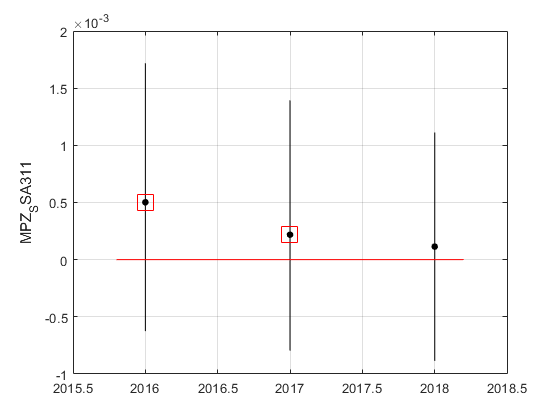

MPZ_result= all_trend_STN(MPZ_tr,MPZ_st); 

plot_10y_in_two(MPZ_result_D, MPZ_st);

MPZ_result_D=MPZ_result;